# MATH 3620 Numerical Analysis

# Homework 3

# 21 Feb 2021

close all; clear all ; clc

## `P1 Convergence of Bernstein Polynomials`

% define anonymous piecewise function
f = @(x) x.*(x >= 0 & x <= 1/2) + (1 - x).*(x > 1/2 & x <= 1);

% estimate rate of convergence of Bnf to f (n >= 1)
% set value of n
% stop when change in value of n does not change mu
n = 40;
% choose two test values, one in each interval
x = [0.28 0.82];
% estimate rate of convergence
fx = f(x);
Bnfx = polyBernstein(f, n, x);
Bnplus1fx = polyBernstein(f, n+1, x);
mu = abs(Bnplus1fx - fx)./abs(Bnfx - fx);
mu

mu =     1.0000    1.0000


`The estimated rate of convergence of Bnf to f for the given function is `$\mu = 1$`, i.e. ``linear convergence``.`

% % testing defined function polyBernstein
% syms u;
% v = sin(2*pi*u);
% w = @(u) sin(2*pi*u);
% % 10th degree Bernstein polynomial
% b10 = bernstein(v, 10, u);
% utest = linspace(0, 1, 6);
% val1 = subs(b10, u, utest);
% val2 = polyBernstein(w, 10, utest);
% vpa(val1 - val2, 5)

## `P2 Chebyshev Polynomials`

% demonstration of the function genChebyshev
n = 5;
T = genChebyshev(n);
fprintf('\n\n The first %d Chebhyshev polynomials on [-1 1] are: %s', n, char(T))



 The first 5 Chebhyshev polynomials on [-1 1] are: [1, x, 2*x^2 - 1, 2*x*(2*x^2 - 1) - x, 1 - 2*x^2 - 2*x*(x - 2*x*(2*x^2 - 1))]

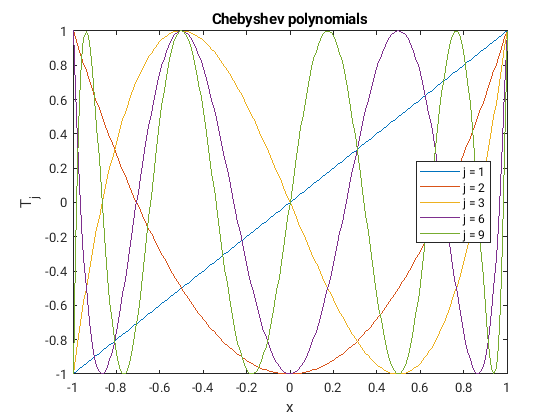

% plot Chebyshev polynomials
legendstr = [];
% for debugging and testing defined function polyChebyshev
%jlist = [0 1 2] 
jlist = [1 2 3 6 9];
for j = 1:length(jlist)
    x = [-1:0.01:1];
    plot(x, polyChebyshev(jlist(j), x))
    hold on
    legendstr= [legendstr, ["j = " + num2str(jlist(j))]];
end
xlabel('x')
ylabel('T_j')
legend(legendstr, "Location","best")
title('Chebyshev polynomials')
hold off

## `P3 Bernstein vs Chebyshev polynomials for function approximation`

% define anonymous function to be approximated
f = @(x) 1./(1 + x.^2);
% interval limits [a, b]
a = -1;
b  =1;
% create node vector [x_0, x_1, ..., x_n]
n = 20;
x = linspace(a, b, n+1);

### `(a)`

% compute Bernstein polynomial B_nf where n = index of last node, i.e. x_n
Bnf = 0;
for k = 0:n
        Bnf = Bnf + (f(-1 + 2*k/n)*nchoosek(n, k)*((x+1).^k).*((1-x).^(n-k)))/(2^n);
end
% compute inf norm of error
einf = max(abs(Bnf - f(x)));

fprintf('The Bernstein polynomial of degree %d has an error with an infinity norm equal to %f.',n, einf)

The Bernstein polynomial of degree 20 has an error with an infinity norm equal to 0.044053.

### `(b)`

% generate first k Chebyshev polynomials
k = 5;
T = genChebyshev(k);
% estimate coefficients a_0, a_1, ..., a_k using Trapezoidal Rule
coeffs = zeros(1, k);
% number of points for trapezoidal rule
np = 201;
h = (b-a)/(np - 1);
nodes = linspace(a, b, np);
for i = 1:length(coeffs)
    for j = 2:length(nodes)-1 % exclude end-points since sqrt(1 - x*x) = 0 at x = -1,1
        coeffs(i) = coeffs(i) + (2/pi)*h*f(nodes(j))*subs(T(i), nodes(j))/sqrt(1 - nodes(j)*nodes(j));
    end
    % correct for missing end-points
    % tuned by trial-and-error
    coeffs(i) = coeffs(i) + (2/pi)*(h/2)*(f(a + h/8)*subs(T(i), a) + f(b - h/8)*subs(T(i), b))/sqrt(1 - (a+h/8)^2);
end
coeffs

coeffs =     1.4121    0.0000   -0.2444    0.0000    0.0410


% check for correctness of coefficients
checkcoeffs = zeros(1, k);
syms x
fx = 1/(1 + x*x);
gx = sqrt(1 - x*x);
for i = 1:length(checkcoeffs)
    hx = T(i)*fx/gx;
    checkcoeffs(i) = (2/pi)*int(hx, x, -1, 1);
end
checkcoeffs

checkcoeffs =     1.4142         0   -0.2426         0    0.0416


`Thus, we see that the coefficents are estimated upto a reasonable degree of precision.`

### `(c)`

nlist = [3 5 7 9 11];
emax = zeros(size(nlist));
for i = 1:length(nlist)
    n = nlist(i);
    xp = linspace(a, b, n+1);
    % get Chebyshev polynomials
    T = genChebyshev(n);
    % compute coefficients
    coeffs = zeros(1, n);
    syms x  
    fx = 1/(1 + x*x);
    gx = sqrt(1 - x*x);
    for j = 1:length(coeffs)
        hx = T(j)*fx/gx;
        if j == 1
            coeffs(j) = (1/pi)*int(hx, x, -1, 1);
        else
            coeffs(j) = (2/pi)*int(hx, x, -1, 1);
        end
    end
    % check approximation error
    fnx = sum(coeffs.*T);
    e = abs(subs(fnx, x, xp) - f(xp));
    emax(i) = vpa(max(e), 5);
    emax
end

emax =     0.0355         0         0         0         0


emax =     0.0355    0.0061         0         0         0


emax =     0.0355    0.0061    0.0012         0         0


emax =     0.0355    0.0061    0.0012    0.0002         0


emax =     0.0355    0.0061    0.0012    0.0002    0.0000


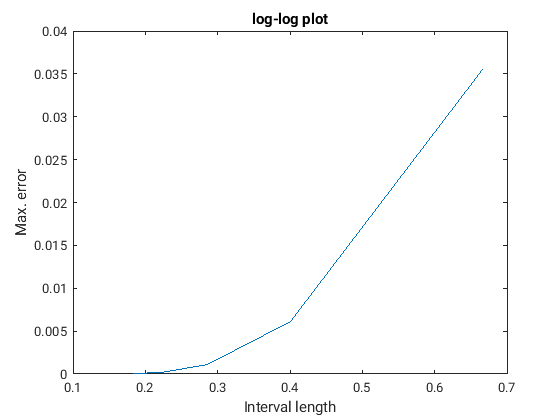

plot((b-a)./nlist, emax)
xlabel('Node spacing')
ylabel('Max. error')
title('log-log plot')

`We see that as we increase the number of nodes, i.e. n, the error reduces to zero. Hence, `$f_n(x)$ `converges to `$f(x)$`.`

### `(d)`

% compare convergence of Bernstein and Chebyshev polynomials
emaxB = zeros(size(nlist));
for i = 1:length(nlist)
    n = nlist(i);
    xp = linspace(a, b, n+1);
    % Bernstein polynomial
    Bnf = 0;
    for k = 0:n
        Bnf = Bnf + (f(-1 + 2*k/n)*nchoosek(n, k)*((xp+1).^k).*((1-xp).^(n-k)))/(2^n);
    end
    % compute inf norm of error
    emaxB(i) = max(abs(Bnf - f(xp)));
end
tbl = table;
tbl.n = nlist;
tbl.eChebyshev = emax;
tbl.eBernstein = emaxB;
disp(tbl)

             n: [3 5 7 9 11]
    eChebyshev: [0.0355 0.0061 0.0012 2.2355e-04 4.0397e-05]
    eBernstein: [0.1333 0.1166 0.0971 0.0821 0.0708]



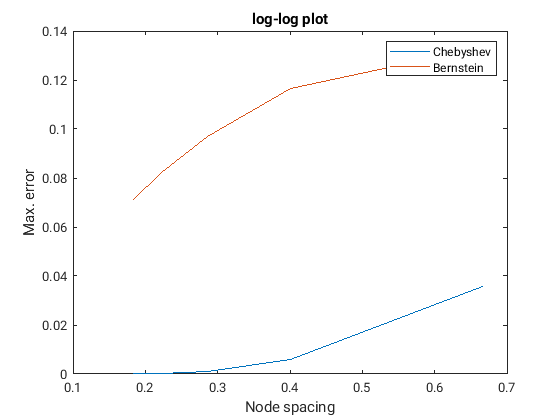

plot((b-a)./nlist, emax)
hold on
plot((b-a)./nlist, emaxB)
xlabel('Node spacing')
ylabel('Max. error')
title('log-log plot')
legend('Chebyshev', 'Bernstein')

`We can see that the Bernstein polynomial approximation converges slower than the Chebyshev polynomial approximation.`

`We can take a look at the log-log plots to compare the rates of convergence. However, it is pretty much clear from the table, and the plot that ``the Chebyshev polynomial approximation converges much faster than the Bernstein polynomial approximation.`

## `Function Definitions`

function val = polyChebyshev(n, x)
    % this function evaluates the n-th Chebyshev polynomial at points
    % defined by the vector x
    val = 0;
    theta = acos(x);
    val = cos(n*theta);
end

function T = genChebyshev(n)
    % this function generates first n Chebyshev polynomials on [-1, 1]
    syms x
    if n == 0
        T = [1];
    end
    if n == 1
            T = [1 x];
    else
        T = [1 x];
        for j = 2:n-1
            T(j+1) = 2*x*T(j) - T(j-1);
        end
    end
end

function val = polyBernstein(f, n, x)
    % this function evaluates the n-th Bernstein polynomial at points
    % defined by the vector x and provided function f
    val = 0;
    for k = 0:n
        val = val + f(k/n)*nchoosek(n, k)*(x.^k).*((1-x).^(n-k));
    end
end